Features = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Features.csv', 'ReadVariableNames',1)
MaxAQI = Features.MaxAQI;
per90 = Features.x90thPercentileAQI;
MedAQI = Features.MedianAQI;
AQI_Class_KMN = Features.AQI_Class_KMN;
AQI_Class_KMR = Features.AQI_Class_KMR;

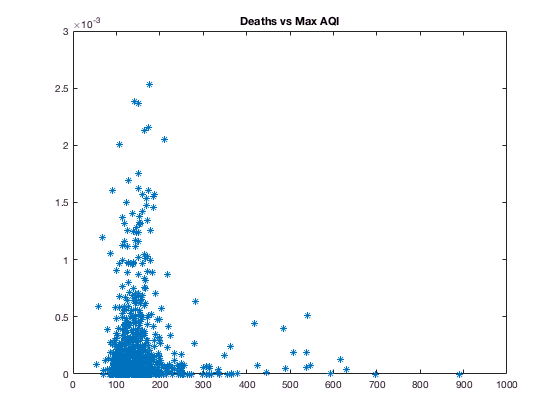

% Deaths vs AQI - Short term spikes 
Deaths = Features.Norm_Deaths;
Dedges = [0:0.0001:0.0025];

figure(1)
plot(MaxAQI, Deaths, '*')
title('Deaths vs Max AQI')
xlim([0,1000])


Deaths_KMN_1 = Deaths(AQI_Class_KMN==1);
Deaths_KMN_2 = Deaths(AQI_Class_KMN==2);
Deaths_KMN_3 = Deaths(AQI_Class_KMN==3);

figure(2)
subplot(3,1,1)
histogram(Deaths_KMN_1, Dedges)
title('Deaths amongst Best AQI Class')
%ylim([0 275])

subplot(3,1,2)
histogram(Deaths_KMN_2, Dedges)
title('Deaths amongst Moderate AQI Class')
%ylim([0 275])

subplot(3,1,3)
histogram(Deaths_KMN_3, Dedges)
title('Deaths amongst Worst AQI Class')
%ylim([0 275])

% ACCOUNT FOR UNBALANCED CLASSES BEFORE MAKING ANY CLAIMSSSSSSSSS!!!
%title('Distribution of Deaths amongst AQI Classes')

% Deaths vs AQI - Long term spikes 
figure(3)
plot(per90, Deaths, '*')
title('Deaths vs 90th Percentie AQI')

figure(4)
plot(MedAQI, Deaths,'*')
title('Deaths vs Median AQI')

Deaths_KMR_1 = Deaths(AQI_Class_KMR==1);
Deaths_KMR_2 = Deaths(AQI_Class_KMR==2);
Deaths_KMR_3 = Deaths(AQI_Class_KMR==3);

figure(5)
subplot(3,1,1)
histogram(Deaths_KMR_1, Dedges)
title('Deaths amongst Best AQI Class')
%ylim([0 300])

subplot(3,1,2)
histogram(Deaths_KMR_2, Dedges)
title('Deaths amongst Moderate AQI Class')
%ylim([0 300])

subplot(3,1,3)
histogram(Deaths_KMR_3, Dedges)
title('Deaths amongst Worst AQI Class')
%ylim([0 300])

% Cases vs AQI 
Cases = Features.Norm_Cases;
Cases_Det_Class = Features.Case_Det_Class;
Cases_Spectral_Class = Features.Case_Spectral_Class; 

